# TRABAJO MAS EFICIENTE

clear all
M = 8;
N = 1000; % Numeros de simbolos
data = randi([0 M-1],N,1);
txSig = pskmod(data,M,0);
%rxSig = awgn(txSig,40);
rxSig = txSig; % quitar esta linea por si algo y descomentar siguiente linea
%scatterplot(rxSig)
Re = real(txSig);
Im = imag(txSig);

## Real e imaginario señal de datos

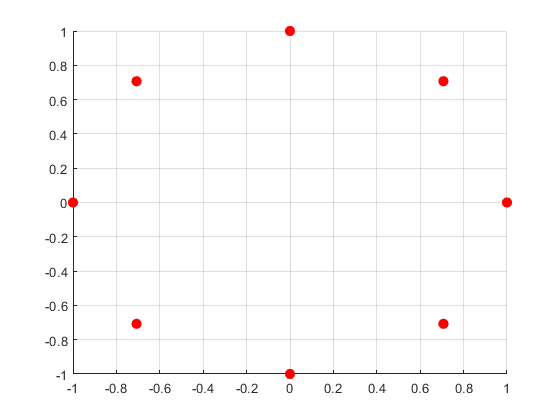

Re = transpose(Re);
Im = transpose(Im);

figure,
c = linspace(1,10,length(Re));
scatter(Re,Im,60,c,'filled','r')
grid on

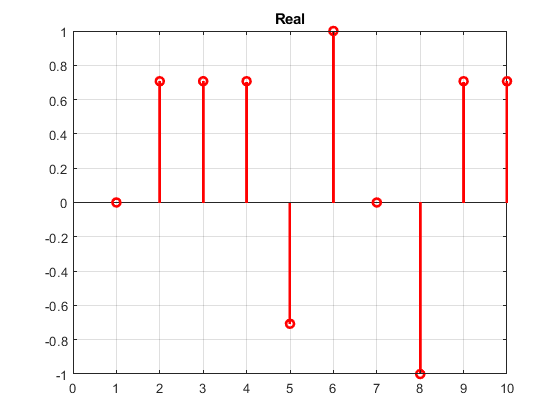


figure,
stem(Re,'r',"LineWidth",2)
title("Real")
axis([0 10 -inf inf])
grid on

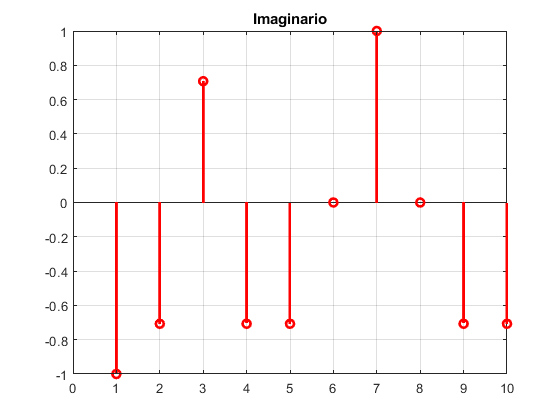


figure, 
stem(Im,'r',"LineWidth",2)
title("Imaginario")
axis([0 10 -inf inf])
grid on

## Filtro coseno elevado

%Filtro Conformador 
%U sobremuestreo
%R roll-off
%L*U debe dar un número par 
R=0.4 ; U=8; L=8; T=1;
h1 = rcosfir(R, L, U, T,'sqrt') ; %la longitud del filtro es 2*L*U+1

## Filtrado transmisor y recpetor parte imaginaria

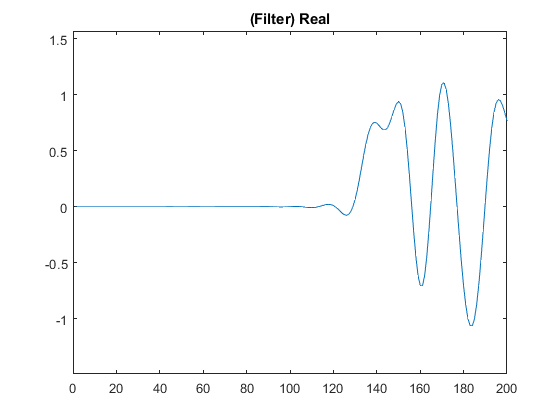

% upsample 
su1=upsample(Re,U);
%filtraje
x1=filter(h1,1,su1); 
%se filtra 2 veces, en el transmisor y en el receptor
x1=filter(h1,1,x1); 
figure,
plot(x1)
title("(Filter) Real")
axis([0 50*U/2 -inf inf]) 


%se agregan ceros debido al transiente del filtro
su=[su1 zeros(1,2*L*U)];
x1=filter(h1,1,su) % filtrado transmisor

x1 =    -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0006    0.0008    0.0007    0.0004   -0.0001   -0.0006   -0.0009   -0.0011   -0.0003    0.0003    0.0008    0.0011    0.0011    0.0007    0.0001   -0.0006   -0.0006   -0.0006   -0.0005   -0.0002    0.0003    0.0007    0.0010    0.0011    0.0002   -0.0004   -0.0010   -0.0013   -0.0013   -0.0010   -0.0003    0.0004    0.0020    0.0026    0.0025    0.0015   -0.0001   -0.0020   -0.0037   -0.0046   -0.0044   -0.0028


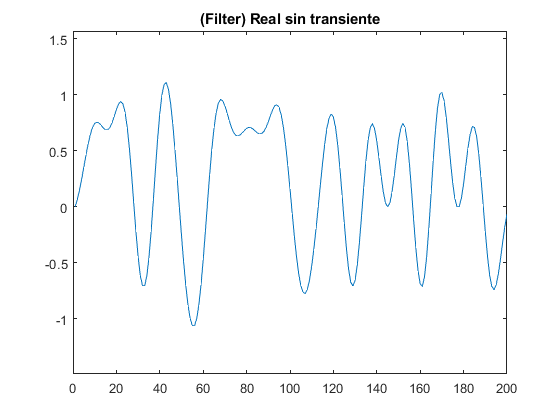

% Canal
x1=filter(h1,1,x1); % Filtrado receptor
%se cortan los ceros que se agregaron 
x1=x1(2*L*U+1:end);
%gráfica de las formas de onda resultantes
figure,
plot(x1)
title("(Filter) Real sin transiente")
axis([0 50*U/2 -inf inf]) 


% recuperación de la secuencia original
s1=downsample(x1, U);

## Recuperacion parte real

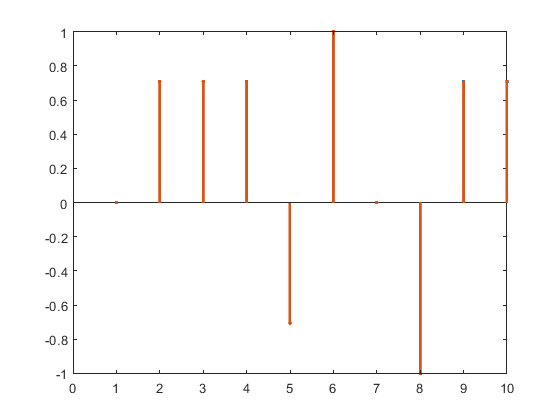

%s1=sign(s1);
%gráfica de las secuencias recuperadas
figure,
stem(Re,'.', 'linewidth', 2), hold on
stem(s1,'.', 'linewidth', 2),
axis([0 10 -inf inf])


isequal(round(Re,1),round(s1,1))

ans = logical
   1


## Filtrado transmisor y receptor parte imaginaria

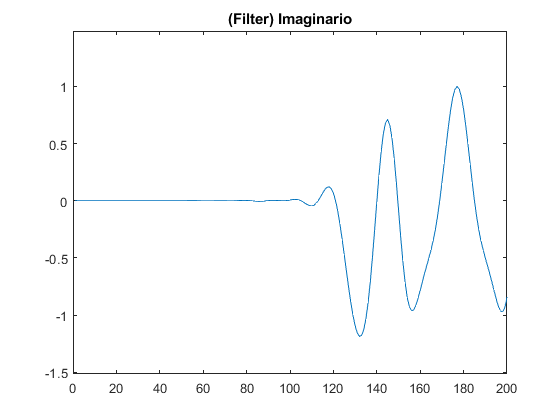

% upsample 
su1=upsample(Im,U);
%filtraje
x1=filter(h1,1,su1); 
%se filtra 2 veces, en el transmisor y en el receptor
x1=filter(h1,1,x1); 
figure,
plot(x1)
title("(Filter) Imaginario")
axis([0 50*U/2 -inf inf]) 


%se agregan ceros debido al transiente del filtro
su=[su1 zeros(1,2*L*U)];
x1=filter(h1,1,su) % filtrado transmisor

x1 =    -0.0008   -0.0011   -0.0010   -0.0005    0.0001    0.0008    0.0013    0.0015    0.0006   -0.0001   -0.0009   -0.0014   -0.0016   -0.0012   -0.0005    0.0004    0.0019    0.0025    0.0024    0.0015   -0.0001   -0.0018   -0.0032   -0.0039   -0.0040   -0.0027   -0.0004    0.0022    0.0045    0.0058    0.0055    0.0036    0.0000   -0.0035   -0.0061   -0.0069   -0.0055   -0.0020    0.0028    0.0073    0.0103    0.0102    0.0067   -0.0001   -0.0089   -0.0174   -0.0232   -0.0240   -0.0177   -0.0056


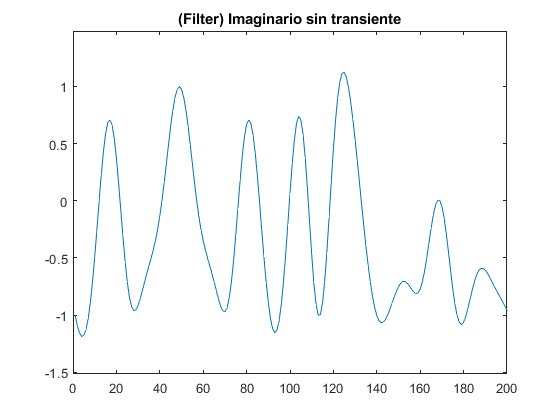

% Canal
x1=filter(h1,1,x1); % Filtrado receptor
%se cortan los ceros que se agregaron 
x1=x1(2*L*U+1:end);
%gráfica de las formas de onda resultantes
figure,
plot(x1)
title("(Filter) Imaginario sin transiente")
axis([0 50*U/2 -inf inf]) 


% recuperación de la secuencia original
s1=downsample(x1, U);

## Recuperacion señal imaginaria

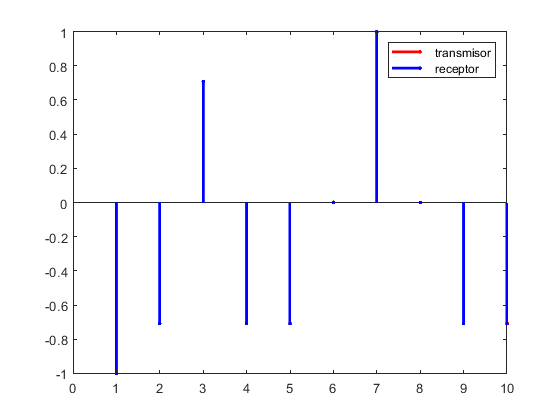

%s1=sign(s1);
%gráfica de las secuencias recuperadas
figure,
stem(Im,'r.', 'linewidth', 2), hold on
stem(s1,'b.', 'linewidth', 2),
legend('transmisor','receptor')
axis([0 10 -inf inf])


isequal(Im,s1)

ans = logical
   0


## Suma de real e imaginario con desplazamiento en frecuencia

f1=5;
Re1=Re*cos(2*pi*f1*t)

R = 2;
a = 0.4;
B = (R*(1+a))/(2)

%%% openExample('comm/ModulateAndDemodulate8PSKSignalExample')

t = -10:0.01:10;
R = 2
a = 0.4
B = R*(1+a)/2
f = 0.5
fh = 0
porta = sin(2*pi*f*t + fh);
figure,
plot(t, porta)

bits = randsrc(10,3,[0 1])
simb = [0 0 0; 0 0 1; 0 1 0; 0 1 1; 1 0 0; 1 0 1; 1 1 0; 1 1 1]

phase = [-112.5; -157.5; -67.5; -22.5; 112.5; 157.5; 67.5; 22.5]

modul = 0

# TRABAJO

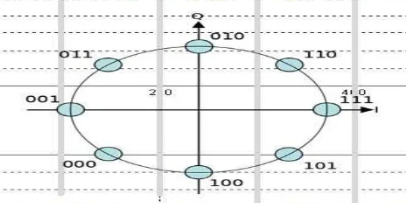

close all
clear all

simb = [0 0 0; 0 0 1; 0 1 0; 0 1 1; 1 0 0; 1 0 1; 1 1 0; 1 1 1] %%% Simbolos de 8-PSK
dSimb = [];  %%% Simbolos de 8-PSK en decimal
for i=1:length(simb)
    dSimb(i,1) = bi2de(simb(i,:),'left-msb');
    i=i+1;
end
dSimb

phase = [225; 180; 90; 135; 270; 315; 45; 0]  %%% Fase en Grados

S = []; %%% [Real, Imaginario]
for i=1:1:length(simb)
    S(i,1) = cos(phase(i)*pi/180);
    S(i,2) = sin(phase(i)*pi/180);   
end
S = round(S,3)

figure,
c = linspace(1,10,length(S(:,2)));
scatter(S(:,1),S(:,2),60,c,'filled')
grid on

n = 10000; %%% Numero de Simbolos
Data = randsrc(n,3,[0 1]) %%% Datos

dData =  []; %%% Datos en decimal
for i=1:length(Data)
    dData(i,1) = bi2de(Data(i,:),'left-msb');
    i=i+1;
end
dData

Out = [];  %%% Datos 8-PSK
for i=1:length(dData)
    for k=1:length(dSimb)
        if dData(i,1)== dSimb(k,1)
            Out(i,:) = S(k,:);
        end
        k=k+1;
    end
    i=i+1;
end
Out

figure,
stem(Out(:,1),'r',"LineWidth",2)
title("Real")
axis([0 10 -inf inf])
grid on

figure, 
stem(Out(:,2),'r',"LineWidth",2)
title("Imaginario")
axis([0 10 -inf inf])
grid on

figure,
c = linspace(1,10,length(Out(:,1)));
scatter(Out(:,1),Out(:,2),60,c,'filled','r') %% X vs Y
grid on